# **Forma Newton a polinomului de interpolare**

**Ce este?**

    Este o varianta alternativa a interpolarii Lagrange, dar contruita diferit. In loc sa foloseasca polinoame fundamentale, polinomul Newton foloseste **diferente** **divizate** si un **format recursiv**

**Avantaje:**

- Este **mai eficient de calculat** decat forma clasica Lagrange

- **Usor de actualiza**t daca adaugi un nou punct

- Se pot folosi **tabele** pentru aorganiza calculele

**Formula Newton**

Polinomul de intrpolare Newton cu diferente divizate:

### 
$$P\left(x\right)=f\left\lbrack x_0 \right\rbrack +f\left\lbrack x_0 ,x_1 \right\rbrack \left(x-x_0 \right)+f\left\lbrack x_0 ,x_1 ,x_2 \right\rbrack \left(x-x_0 \right)\left(x-x_1 \right)+\ldotp \ldotp \ldotp$$


unde:

- `f[x0]` este valoarea functiei în punctul x₀.

- `f[x0, x1]` este prima diferenta divizata.

- `f[x0, x1, x2]` este a doua diferenta divizata

**Utilizare practica:**

- Se consturieste **tabela triunghiulara **de diferente

- Evaluarea se face eficient, folosind relatii recursive

# **Interpolarea Hermite cu noduri duble**

**Ce este ?**

    Este o metoda practica de a construi polinomul Hermite **folosind o tabela de diferente divizate**, dar adaptata pt cazul in care aceleasi noduri se repeta (de doua ori) pentru a include si derivata

**Cum functioneaza?**

- Fiecare nod apare **de doua ori in tabe**l: o data pentru valoare, o data pentru derivata

- Prima diferenta divizata dintre doua noduri egale este **derivata**

- Restul tabelului se completeaza ca in metoda Newton obisnuita

**Avantaje:**

- Este o metoda generala si usor de implementat in cod

- Functioneaza pentur orice functie derivabila in noduri

**Caracteristici:**

- Polinomul rezultat are un **grad mai mare**, pentru ca tine cont si de derivata (2n-1)

- Nodurile apar de **doua ori (sau mai multe) **in tabelele de diferente

**Structura polinomului:**

$H_n \left(x\right)=\sum_{k=0}^m \sum_{j=0}^{r_k } h_{\textrm{kj}} \left(x\right)f^{\left(j\right)} \left(x_k \right)$ ,

**Strategia:**

- Construim un **vector **`z` unde fiecare nod apare de doua ori: `z = [x(1), x(1), x(2), x(2), ..., x(n), x(n)]`.

- Construim un **tabel de diferente divizate **`Q`:

- `Q(i,1) = f(xi)`

- `Q(i+1,1) = f(xi)` (pentru nod dublu)

- `Q(i+1,2) = df(xi)` (derivata)

- `Q(i,2) = (Q(i+1,1) - Q(i,1)) / (z(i+1) - z(i))` pentru restul

- Construim polinomul Hermite sub formă de Newton.

- Evaluam acest polinom în fiecare `x_eval`.

f = @(x) sin(x);
x = [0, pi/4, pi/2];
x_eval = pi/6;

[val_interp, val_exacta, eroare, xx, yy] = Hermite(f, x, x_eval);

fprintf("Interpolare Hermite la x = %.4f: %.10f\n", x_eval, val_interp);

Interpolare Hermite la x = 0.5236: 0.5000190279


fprintf("Valoare exacta:              %.10f\n", val_exacta);

Valoare exacta:              0.5000000000


fprintf("Eroare absoluta:             %.2e\n", eroare);

Eroare absoluta:             1.90e-05


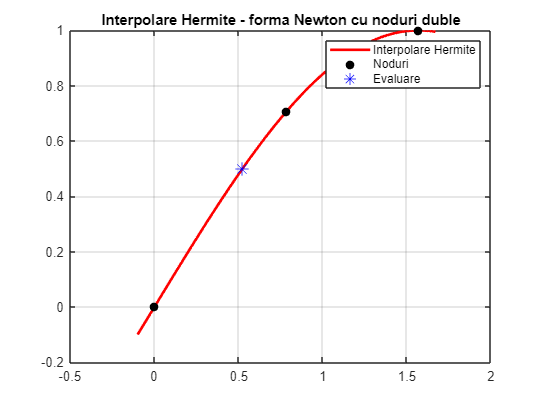


% Grafic
figure;
plot(xx, yy, 'r-', 'LineWidth', 2); hold on;
plot(x, f(x), 'ko', 'MarkerFaceColor', 'k');
plot(x_eval, val_interp, 'b*', 'MarkerSize', 10);
legend('Interpolare Hermite', 'Noduri', 'Evaluare');
title('Interpolare Hermite - forma Newton cu noduri duble');
grid on;

# Interpolarea Aitken (schema Neville)

**Ce este?**

    Este o metoda numerica folosita pt a** aproxima valoarea** unei functii intr-un punct, f**ara sa construiasca explicit polinomul** de interpolare

    Este o alternativa eficienta la metodele clasice (Lagrange/Newton), ideal cand ai

- putine puncte

- vrei **doar valoarea intr-un punct, nu tot polinomul**

**Cum functioneaza?**

    Metoda contruieste recursib o tabela triunghiulara de valori $P\left(i,j\right)$ bazata pe urmatoarea formula:

$P_{i,j} \left(x\right)=\frac{\left(x-x_i \right)\cdot P_{i+1,j} \left(x\right)-\left(x-x_j \right)\cdot P_{i,j-1} \left(x\right)}{x_j -x_i }$ Aceasta conbina valorile in mod recursiv pentru a obtine o aproximare din ce in ce mai precisa, care converge catre valoarea dorita

**Avantaje**

- Nu construieste explicit un polinom

- Usor d implementat

- Eficient intr-un singur punct

f = @(x) sin(x);
x = [0, pi/4, pi/2];
x_eval = pi/6;

[val, exact, err, xx, yy] = Aitken(f, x, x_eval);

fprintf("Aitken: f(%.4f) ≈ %.10f, exact: %.10f, eroare: %.2e\n", ...
         x_eval, val, exact, err);

Aitken: f(0.5236) ≈ 0.5174282499, exact: 0.5000000000, eroare: 1.74e-02


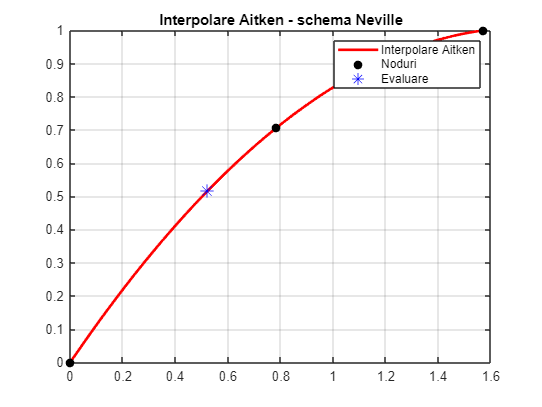


% Plot
figure;
plot(xx, yy, 'r-', 'LineWidth', 2); hold on;
plot(x, f(x), 'ko', 'MarkerFaceColor', 'k');
plot(x_eval, val, 'b*', 'MarkerSize', 10);
legend('Interpolare Aitken', 'Noduri', 'Evaluare');
title('Interpolare Aitken - schema Neville');
grid on;

fprintf("Aitken: f(%.2f) ≈ %.10f, eroare: %.2e\n", x_eval, p_aitken, err_aitken);

Aitken: f(0.52) ≈ 2.1308966387, eroare: 1.39e-02


# Diferente divizate

**Ce sunt?**

    Diferentele divizate sunt o forma generala de "rata de schimbare" intre valori alte functiei. Ele sunt folosite pentru a calcula coeficientii polinomului Newton

# Interpolarea Newton

**Ce este?**

    Este o metoda de constructie a polinomului de interpolare care se baseaza pe diferente divizate recursive. Este o alternativa la forma Lagrange

**Cum funcitoneaza?**

    1. Se calculeaza diferentele divizate intr-un tabel

-   Primul ran: valorile functiei

- Randurile urmatoare **recursiv**:

            
$$f\left\lbrack x_i ,x_{i+1} \right\rbrack =\frac{f\left\lbrack x_{i+1} \right\rbrack -f\left\lbrack x_i \right\rbrack }{x_{i+1} -x_i }$$


            
$$f\left\lbrack x_i ,x_{i+1} ,x_{i+2} \right\rbrack =\frac{f\left\lbrack x_{i+1} ,x_{i+2} \right\rbrack -f\left\lbrack x_i ,x_{i+1} \right\rbrack }{x_{i+2} -x_i }$$


    2. Polinomul se construieste progresib prin inmultiri si sume 

**Avantaje**

- Usor de extins

- eficient numeric

- potrivit pentru constructie treptata a polinomului

f = @(x) sin(x);
x = [0, pi/4, pi/2];
x_eval = pi/6;

[p, exact, err, xx, yy, coef] = Newton(f, x, x_eval);

fprintf("Newton: f(%.4f) ≈ %.10f, exact: %.10f, eroare: %.2e\n", ...
        x_eval, p, exact, err);

Newton: f(0.5236) ≈ 0.5174282499, exact: 0.5000000000, eroare: 1.74e-02


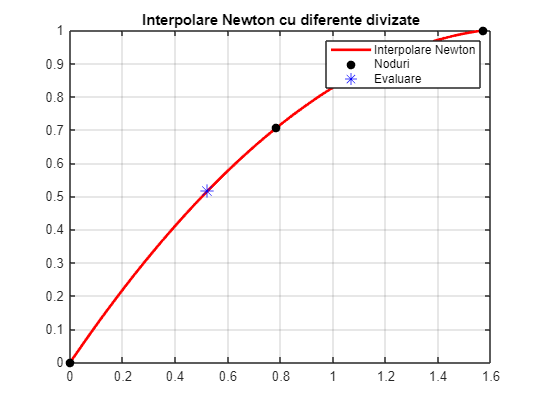


% Plot
figure;
plot(xx, yy, 'r-', 'LineWidth', 2); hold on;
plot(x, f(x), 'ko', 'MarkerFaceColor', 'k');
plot(x_eval, p, 'b*', 'MarkerSize', 10);
legend('Interpolare Newton', 'Noduri', 'Evaluare');
title('Interpolare Newton cu diferente divizate');
grid on;